# Figures 8 and 9: 

# Comparing RGBW and RGB sensors

## Initialize ISET

We will need to clear the data midway through, so we set ieInit to clear the data.

ieInit;
initClear = ieSessionGet('init clear');
ieSessionSet('init clear',true);

## Initialize the data objects

These are the sensor models and default image processor

sensorRGBW = sensorCreate('ar0132at',[],'rgbw');
sensorRGB  = sensorCreate('ar0132at',[],'rgb');
sensorRGB  = sensorSet(sensorRGB,'exp time',1/60);
sensorRGBW = sensorSet(sensorRGBW,'exp time',1/60);

ip = ipCreate;
ip = ipSet(ip,'demosaic method','Adaptive Laplacian'); 

The whole set of Fruit images are here:

  [https://stacks.stanford.edu/file/druid:tb259jf5957/ISET_fruit.zip](https://stacks.stanford.edu/file/druid:tb259jf5957/ISET_fruit.zip)

We put the single FruitMCC.mat image in the ISET HDR Sensor SDR collection.  It should be downloaded by the isethdrsensorSDR script.

filename = 'FruitMCC.mat';
scene = sceneFromFile(filename,'multispectral',[],[],400:10:700);

Reading multispectral data with mcCOEF.
Saved using principal component method


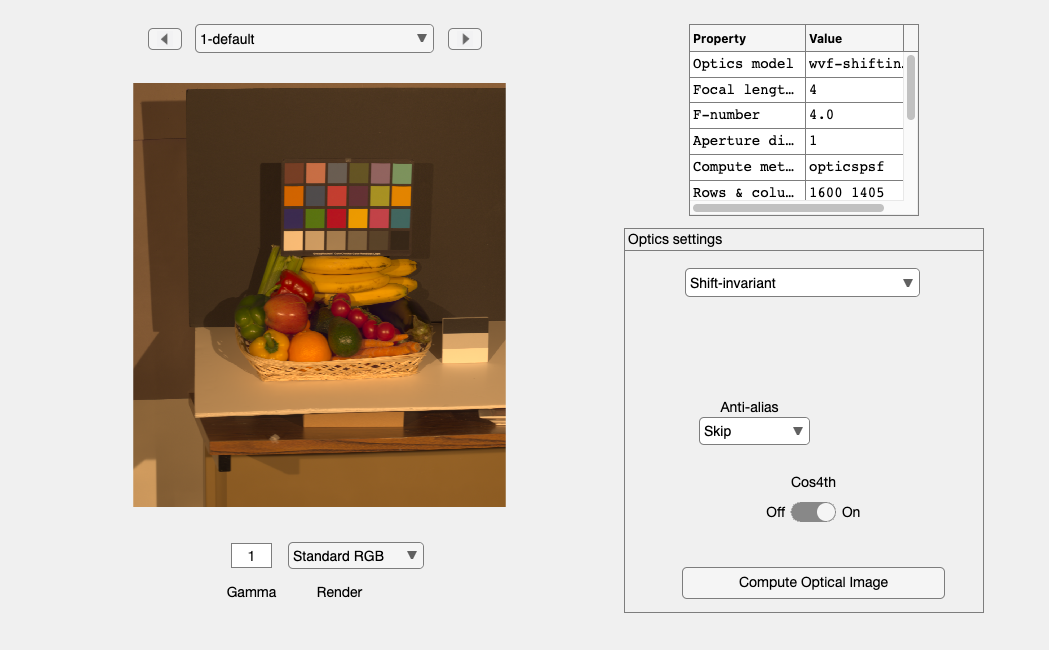

oi = piOICreate(sceneGet(scene,'photons'));
oiWindow(oi);

Create the images.  Remember that the neural networks and Python had to be set up.

% Choose two dark levels
lux = [0.1, 0.25];
nLevels = numel(lux);

% For each level
ipRGB    = cell(nLevels,1);
ipRGBNN  = cell(nLevels,1);
ipRGBWNN = cell(nLevels,1);

ssim_rgb    = zeros(nLevels,1);
ssim_rgbnn  = zeros(nLevels,1);
ssim_rgbwNN = zeros(nLevels,1);

sensorRGB = sensorSet(sensorRGB,'pixel size',4e-6);

Fill factor may have changed. You can use: size same fill factor


sensorRGB = sensorSet(sensorRGB, 'sensor size', [512, 512]);
sensorRGBW = sensorSet(sensorRGBW,'pixel size',4e-6);

Fill factor may have changed. You can use: size same fill factor


sensorRGBW = sensorSet(sensorRGBW, 'sensor size', [512, 512]);


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.
INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.
INFO: Input image is RGB
INFO: Demosaicing is successfully completed.
INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.



for ii = 1:numel(lux)
    oi = oiAdjustIlluminance(oi, lux(ii));

    % rgb
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB{ii} = ipCompute(ip, thisSensorRGB);
    ipWindow(ipRGB{ii}); rgbImg = ipGet(ipRGB{ii}, 'srgb');

    % rgb using restormer
    ipRGBNN{ii} = ipCompute(ip, thisSensorRGB, 'network demosaic','ar0132at-rgb');
    ipWindow(ipRGBNN{ii}); rgbNNImg = ipGet(ipRGBNN{ii}, 'srgb');

    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipRGBWNN{ii} = ipCompute(ip,thisSensorRGBW, 'network demosaic','ar0132at-rgbw');
    ipWindow(ipRGBWNN{ii}); rgbwNNImg = ipGet(ipRGBWNN{ii}, 'srgb');

    if ii==1
        % Make the ground truth image data the first time
        sensorI = sensorCreateIdeal('match',sensorRGB);
        sensorI = sensorCompute(sensorI,oi);
        % sensorWindow(sensorI(3));
        
        % Ground truth images
        gtImg(:,:,1) = sensorI(1).data.volts;
        gtImg(:,:,2) = sensorI(2).data.volts;
        gtImg(:,:,3) = sensorI(3).data.volts;

        ipIdeal = ipRGB{1};
        ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
        ipIdeal = ipSet(ipIdeal, 'transform method', 'current');

        % Set the sensor space image in the image processing structure
        ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

        % Compute the final image processing
        ipIdeal = ipCompute(ipIdeal, thisSensorRGB);

        ipWindow(ipIdeal);

        rgbGT = ipGet(ipIdeal, 'srgb');
        rgbGT = ieScale(rgbGT, 1);
    end
    
    %{
    savedPath = fullfile(isethdrsensorRootPath,'figures/fig_RGBWvsRGB');
    imwrite(rgbImg,sprintf('%s/rgb-%d.png',savedPath,ii));
    imwrite(rgbNNImg,sprintf('%s/rgbNN-%d.png',savedPath,ii));
    imwrite(rgbwNNImg,sprintf('%s/rgbwNN-%d.png',savedPath,ii));
    %}

    rgbImg    = ieScale(rgbImg, 1);
    rgbNNImg  = ieScale(rgbNNImg, 1);
    rgbwNNImg = ieScale(rgbwNNImg, 1);
    
    %{
     psnr_rgb(ii)    = psnr(rgbImg,rgbGT);
     psnr_rgbnn(ii)  = psnr(rgbNNImg, rgbGT);
     psnr_rgbwNN(ii) = psnr(rgbwNNImg, rgbGT);
    %}

    % Calculate SSIM 
     ssim_rgb(ii)    = ssim(rgbImg, rgbGT);
     ssim_rgbnn(ii)  = ssim(rgbNNImg, rgbGT);
     ssim_rgbwNN(ii) = ssim(rgbwNNImg, rgbGT);    

end

sensorName = {'ipRGB','ipRGBNN','ipRGBWNN'};
sensorList{1} = ipRGB;
sensorList{2} = ipRGBNN;
sensorList{3} = ipRGBWNN;

## This is really part of Figure 9

ieNewGraphWin;
% Blue line with circle markers
plot(lux, ssim_rgb(:), 'color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 6); hold on  
% Red line with square markers
plot(lux, ssim_rgbnn(:), 'color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2, 'LineStyle', '--', 'Marker', 's', 'MarkerSize', 6);         
% Green line with diamond markers
plot(lux, ssim_rgbwNN(:), 'color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2, 'LineStyle', ':', 'Marker', 'd', 'MarkerSize', 6);       

legend('RGB', 'RGB-NN', 'RGBW-NN', 'FontSize', 14, 'Location', 'Best');
xlabel('Log Mean Illuminance (lux)', 'FontSize', 16);
ylabel('SSIM', 'FontSize', 16);
set(gca, 'FontSize', 16);
set(gca, 'XScale', 'log');

## Illustrate the noise

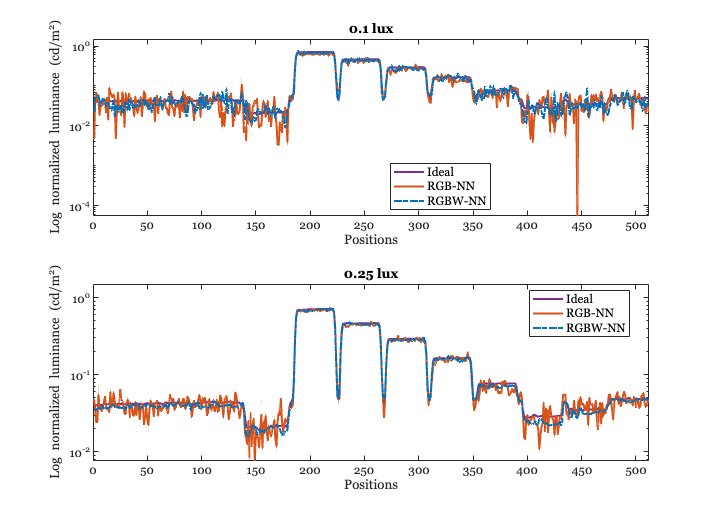

ieNewGraphWin;
whichLine = 155;

% Define colors and line styles for better distinction
colors = {[0.4660, 0.6740, 0.1880],[0.8500, 0.3250, 0.0980],  [0.0000, 0.4470, 0.7410]};
lineStyles = {'-', '-', '-.'};
titleNames = {'0.1 lux', '0.25 lux'};
for nn = 1:2
    subplot(2, 1, nn);
    % Plot for ipIdeal
    data = ipGet(ipIdeal, 'data luminance');
    data = ieScale(data, 1);
    plot(data(whichLine,:,1), 'color', [0.4940, 0.1840, 0.5560], 'LineWidth', 2, 'LineStyle', '-'); hold on  
    
    % Plot for ipRGB
    for ss = 2:3
        thisIP = sensorList{ss};
        data = ipGet(thisIP{nn}, 'data luminance');
        data = ieScale(data, 1);
        % data = ipGet(thisSensor{nn}, 'data display');data = data(:,:,2);
        plot(data(whichLine,:,1), 'color', colors{ss}, 'LineWidth', 2, 'LineStyle', lineStyles{ss}); 
    end

    % Customize each subplot
    legend('Ideal', 'RGB-NN', 'RGBW-NN', 'FontSize', 12, 'Location', 'Best');
    xlabel('Positions', 'FontSize', 14);
    ylabel('Log normalized luminance (cd/m^2)', 'FontSize', 12);
    set(gca, 'FontSize', 12);
    xlim([0, 512]);
    ylim([0, 1.5]);
    title(titleNames{nn})
    set(gca, 'YScale', 'log');
end

## Create the two sensors and IP

ieInit;

sensorRGBW = sensorCreate('ar0132at',[],'rgbw');
sensorRGB  = sensorCreate('ar0132at',[],'rgb');

sensorRGB  = sensorSet(sensorRGB,'exp time',1/60);
sensorRGBW = sensorSet(sensorRGBW,'exp time',1/60);

ip = ipCreate;
ip = ipSet(ip,'demosaic method','Adaptive Laplacian');

## Color test scene

scene = sceneCreate('macbeth',80);

oi = oiCreate;
oi = oiCompute(oi, scene,'crop',true,'pixel size', 3e-6);

% Match the sensor spatial parameters to the OI
sensorRGB = sensorSet(sensorRGB,'match oi',oi);
sensorRGBW = sensorSet(sensorRGBW,'match oi',oi);

## Start low, and progress to high, optical image illuminance

INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.77 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.06 seconds


INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.58 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.11 seconds


INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.37 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.13 seconds


INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.43 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.31 seconds


INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.41 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.03 seconds


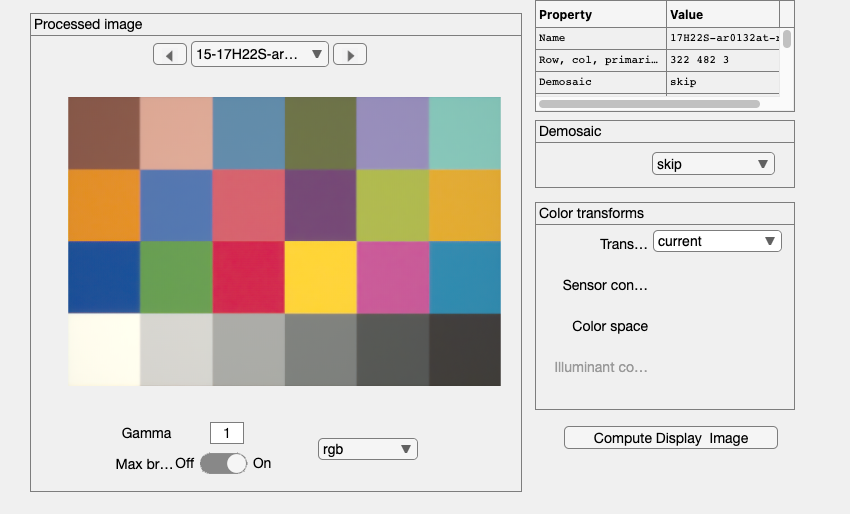

% We used this for the paper
% lux = [0.1: 0.1:1, 2:10];   % Zhenyi's original

% But we suggest using this to keep it short.
lux = logspace(-2,1,5);      % Five levels
%
for ii = 1:numel(lux)
    oi = oiAdjustIlluminance(oi, lux(ii));

    
    % rgb
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB = ipCompute(ip, thisSensorRGB);
    ipWindow(ipRGB); rgbImg = ipGet(ipRGB, 'srgb');

    % rgbw using restormer
    ipRGBNN = ipComputeNN(thisSensorRGB, 'ar0132at-rgb');
    ipWindow(ipRGBNN); rgbNNImg = ipGet(ipRGBNN, 'srgb');

    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipRGBWNN = ipComputeNN(thisSensorRGBW, 'ar0132at-rgbw');
    ipWindow(ipRGBWNN); rgbwNNImg = ipGet(ipRGBWNN, 'srgb');

    if ii==1
        % Make the ground truth image data the first time
        sensorI = sensorCreateIdeal('match',sensorRGB);
        sensorI = sensorCompute(sensorI,oi);
        % sensorWindow(sensorI(3));
        gtImg(:,:,1) = sensorI(1).data.volts;
        gtImg(:,:,2) = sensorI(2).data.volts;
        gtImg(:,:,3) = sensorI(3).data.volts;

        ipIdeal = ipRGB;
        ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
        ipIdeal = ipSet(ipIdeal, 'transform method', 'current');
        % Set the sensor space image in the image processing structure
        ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

        % Compute the final image processing
        ipIdeal = ipCompute(ipIdeal, thisSensorRGB);

        % ipWindow(ipIdeal);
        rgbGT = ipGet(ipIdeal, 'srgb');
        rgbGT = ieScale(rgbGT, 1);
    end

    rgbImg    = ieScale(rgbImg, 1);
    rgbNNImg   = ieScale(rgbNNImg, 1);
    rgbwNNImg = ieScale(rgbwNNImg, 1);
    
    dE_rgb(ii)    = mean2(imcolordiff(rgbGT, rgbImg));
    dE_rgbnn(ii)  = mean2(imcolordiff(rgbGT, rgbNNImg));
    dE_rgbwNN(ii) = mean2(imcolordiff(rgbGT, rgbwNNImg));
end

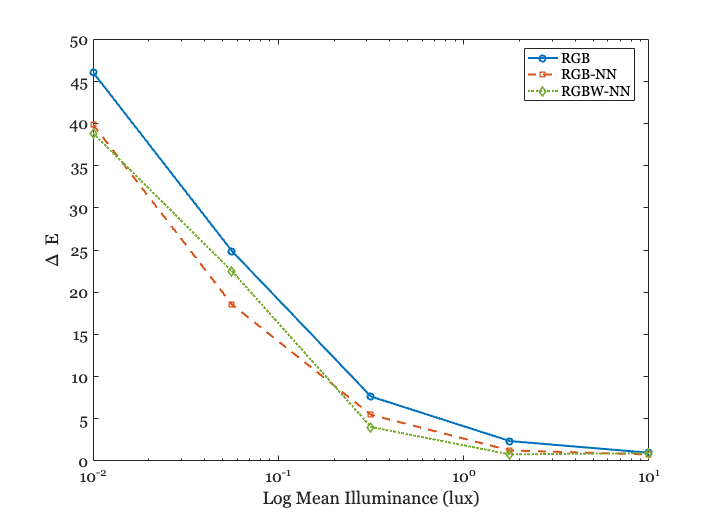

ieNewGraphWin;

% Blue line with circle markers
plot(lux, dE_rgb(:), 'color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 6); hold on  
% Red line with square markers
plot(lux, dE_rgbnn(:), 'color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2, 'LineStyle', '--', 'Marker', 's', 'MarkerSize', 6);         
% Green line with diamond markers
plot(lux, dE_rgbwNN(:), 'color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2, 'LineStyle', ':', 'Marker', 'd', 'MarkerSize', 6);       

legend('RGB', 'RGB-NN', 'RGBW-NN', 'FontSize', 14, 'Location', 'Best');
xlabel('Log Mean Illuminance (lux)', 'FontSize', 16);
ylabel('\Delta E', 'FontSize', 16);
set(gca, 'FontSize', 16);
set(gca, 'XScale', 'log');

%{
imwrite(rgbNNImg,'~/Desktop/rgbNN.png')
imwrite(rgbwNNImg,'~/Desktop/rgbwNN.png')
imwrite(rgbImg,'~/Desktop/rgb.png')
%}

## Not in the paper any more

%{
figure;
% Blue line with circle markers
plot(lux, psnr_rgb(:), 'color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 6); hold on  
% Red line with square markers
plot(lux, psnr_rgbnn(:), 'color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2, 'LineStyle', '--', 'Marker', 's', 'MarkerSize', 6);         
% Green line with diamond markers
plot(lux, psnr_rgbwNN(:), 'color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2, 'LineStyle', ':', 'Marker', 'd', 'MarkerSize', 6);       

legend('RGB', 'RGB-NN', 'RGBW-NN', 'FontSize', 14, 'Location', 'Best');
xlabel('Log Mean Illuminance (lux)', 'FontSize', 16);
ylabel('PSNR', 'FontSize', 16);
set(gca, 'FontSize', 16);
set(gca, 'XScale', 'log');
%}

ieSessionSet('init clear',initClear);

Unrecognized function or variable 'ssim_rgb'.

% Plot for deltaE
%{
figure;

yyaxis left;
plot(lux, dE_rgb(:), 'color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 6); hold on  
plot(lux, dE_rgbnn(:), 'color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2, 'LineStyle', '--', 'Marker', 's', 'MarkerSize', 6);         
plot(lux, dE_rgbwNN(:), 'color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2, 'LineStyle', ':', 'Marker', 'd', 'MarkerSize', 6);       
ylabel('deltaE', 'FontSize', 16);
%}

%{

oi = oiAdjustIlluminance(oi, 1);
for ii = 1:numel(lux)
    % oi = oiAdjustIlluminance(oi, lux(ii));
    sensorRGB  = sensorSet(sensorRGB,'exp time', expTime(ii));
    sensorRGBW = sensorSet(sensorRGBW,'exp time',expTime(ii));
    
    % rgb
    thisSensorRGB = sensorCompute(sensorRGB,oi);

    % rgb using restormer
    ipRGBNN = ipComputeNN(thisSensorRGB, 'ar0132at-rgb');

    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipRGBWNN = ipComputeNN(thisSensorRGBW, 'ar0132at-rgbw');

end

for ii = 1:numel(lux)
    % oi = oiAdjustIlluminance(oi, lux(ii));
    sensorRGB  = sensorSet(sensorRGB,'exp time',expTime(ii));
    sensorRGBW = sensorSet(sensorRGBW,'exp time',expTime(ii));
    
    % rgb
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB = ipCompute(ip, thisSensorRGB);
    ipWindow(ipRGB); rgbImg = ipGet(ipRGB, 'srgb');

    % rgbw using restormer
    ipEXR = sprintf('/Users/zhenyi/git_repo/dev/isethdrsensor/local/exr/05-Aug-2024/ISET_Sensor_RGB/normalized/13H46S-ar0132at-rgb-%.2f.exr', sensorGet(thisSensorRGB, 'exp time', 'ms'));
    ipRGBNN = ipComputeNN(thisSensorRGB, 'ar0132at-rgb',ipEXR);
    ipWindow(ipRGBNN); rgbNNImg = ipGet(ipRGBNN, 'srgb');
    %{
    % rgbw
    
    ipRGBW = ipCompute(ip, thisSensorRGBW, 'hdr white', true);
    ipWindow(ipRGBW); rgbwImg = ipGet(ipRGBW, 'srgb');
    %}

    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipEXR = sprintf('/Users/zhenyi/git_repo/dev/isethdrsensor/local/exr/05-Aug-2024/ISET_Sensor_RGBW/normalized/13H46S-ar0132at-rgbw-%.2f.exr', sensorGet(thisSensorRGBW, 'exp time', 'ms'));
    ipRGBWNN = ipComputeNN(thisSensorRGBW, 'ar0132at-rgbw',ipEXR);
    ipWindow(ipRGBWNN); rgbwNNImg = ipGet(ipRGBWNN, 'srgb');

    if ii==1
        % Make the ground truth image data the first time
        sensorI = sensorCreateIdeal('match',sensorRGB);
        sensorI = sensorCompute(sensorI,oi);
        % sensorWindow(sensorI(3));
        gtImg(:,:,1) = sensorI(1).data.volts;
        gtImg(:,:,2) = sensorI(2).data.volts;
        gtImg(:,:,3) = sensorI(3).data.volts;

        ipIdeal = ipRGB;
        ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
        ipIdeal = ipSet(ipIdeal, 'transform method', 'current');
        % Set the sensor space image in the image processing structure
        ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

        % Compute the final image processing
        ipIdeal = ipCompute(ipIdeal, thisSensorRGB);

        % ipWindow(ipIdeal);
        rgbGT = ipGet(ipIdeal, 'srgb');
        rgbGT = ieScale(rgbGT, 1);
    end

    rgbImg    = ieScale(rgbImg, 1);
    rgbNNImg  = ieScale(rgbNNImg, 1);
    rgbwNNImg = ieScale(rgbwNNImg, 1);
    
    dE_rgb(ii)    = mean2(imcolordiff(rgbGT, rgbImg));
    dE_rgbnn(ii)  = mean2(imcolordiff(rgbGT, rgbNNImg));
    dE_rgbwNN(ii) = mean2(imcolordiff(rgbGT, rgbwNNImg));
end
%}